# Dynamic Structural Econometrics -- Dynamic games

Prepared by Aaron Barkley, University of Melbourne

## Introduction and model

We now investigate how conditional choice probability methods can be extended to the estimation of dynamic games. We focus on an entry and exit game, a canonical example within the IO literature that has been used frequently in applied work (Ryan (2012), Collard-Wexler (2013) and continues to be applied in recent studies (Caoui et al (2022)) and see advancements in methodology (Srisuma (2013, Miessi Sanches et al (2016)). See also Aguirregabiria el at (2021) for an extensive overview of empirical studies of dynamic games. 

The basic structure of the game is as follows:

- Time $t$ is discrete, with $t=1,2,...,\infty$.

- There are $I$ firms in each market $m$, with $N_m$ markets total.

- The environment is stationary (choice probabilities, state transitions, and flow utilities only depend on time through the realization of the state variable in that period).

- Each period, firms (simultaneously) make decisions about whether to enter the market (if they are currently out of the market) or permanently exit the market (if they are currently an incumbent). A firm that exits that market is replaced next period by a potential entrant.

- Firms have private information about their payoffs through an identically and independtly distributed random variable $\epsilon_{jt}^{(i)}$ for each period $t$, firm $i$, and choice $j$.

The primary difference between the single-agent framework and the multi-agent framework is that both agents' flow utilities and the evolution of state variables is determined by the realizations of the actions of all players. To account for this, our notation will adjust following Arcidiacono and Miller (2011) to "big" and "little" notation: "big" notation (capital letters) denotes flow utilities $U^{(i)}$, choice probabilities $P$, and state transitions $F_j$ for firm $i$ *conditional on the realizations for opponents' actions *$d^{(-i){$. Because these terms condition on the outcomes of decisions that firm $i$ will not know when they make their own choice, due to the simultaneity of decisions, we need to integrate over the distributions of the vector of choices in order to obtain the "little" notation that we have used in previous notes.

- Utility for firm $i$ to enter/remain in the market is given by


$$U^{(i)}_2(x_t^{(i)}, s_t^{(i)},d_t^{(-i)}) = \theta_0 + \theta_1 x_1 + \theta_2 s_t + \theta_3 \sum_{i'\neq i} d_{2t}^{(i')} + \theta_4 (1-d_{2,t-1}^{(i)})$$


where $x_1$ is a permanent market characteristic affecting all firms, $s_t$ is a transitory market characteristic affecting all firms, $\sum_{i'  \neq i} d_{2t}^{(i')}$ is the sum of $i$'s (potential) competitors that are active in the market in period $t$, and $\theta_4$ captures the entry cost that firm $i$ incurs if it was not active in the previous period.

- Define $z_t$ to be the set of state variables. Consistent with our previous notation, let $p^{(i)}_j(z_t)$be the probability that firm $i$ chooses choice $j$ conditional on state $z_t$.

- The "big P" probability of observing a set of choices $d^{(-i)}_t$ from $i$'s competitors in period $t$ conditional on state $z_t$ is


$$P(d_t^{(-i)} | z_t) = \prod_{i'\neq i} \Big( \sum_{j=1}^J d_{jt}^{(i')} p_j^{(i')}(z_t) \Big)$$


- Then we can express the expected flow payoff for firm $i$ from choosing $j$ in state $z_t$, net of the choice-specific private payoff term $\epsilon_{jt}^{(i)}$, as


$$u_j^{(i)}(z_t) = \sum_{d_t^{(-i)} \in J^{I-1}} P(d_t^{(-i)} | z_t) U_j^{(i)} (z_t, d_t^{(-i)})$$


- Similarly, the distribution over next period's state variables when firm $i$ makes choice $j$, $f_j^{(i)}(z_{t+1} | z_t)$, can be express as


$$f_j^{(i)}(z_{t+1} | z_t) = \sum_{d_t^{(-i)} \in J^{I-1}} P(d_t^{(-i)} | z_t)  F_j(z_{t+1} | z_t, d_t^{(-i)})$$


- These terms can be used to express the conditional value function $v_j^{(i)}(z_t)$ in a familiar form as


$$v_j^{(i)}(z_t) = u_j^{(i)}(z_t) + \beta \sum_{z_{t+1}=1}^Z \Big[ v_k^{(i)}(z_{t+1}) + \psi_k[p^{(i)}(z_{t+1})] \Big]f_j^{(i)}(z_{t+1} | z_t)$$


- Assuming that $\epsilon_{jt}^{(i)}$ are i.i.d. Type I Extreme Value and exploiting the terminal decision of exiting the market allows us to express the conditional value function using the one-period ahead conditional choice probabilities:


$$v_2^{(i)}(x_t,s_t) = u_2^{(i)}(x_t,s_t) - \beta \sum_{x_{t+1} \in X} \sum_{s_{t+1} \in S} [\log(p_1^{(i)}(x_{t+1},s_{t+1}) ] f_2^{(i)}(x_{t+1},s_{t+1} | x_t, s_t)$$


- Lastly, we have data on market-level prices $y$, which we model as a linear function of the state variables, number of firms, and a random, idiosyncratic term $\eta_t$ that is assumed to follow a normal distribution with variance term $\sigma$. (*Note: market-level prices are primarily useful in estimating models with unobserved heterogeneity, as they can serve as a noisy signal of changes in the time-varying state *$s_t$ *when this is assumed to be unobserved. Because for now w have assumed that *$s_t$ *is observed, we can ignore the price data.)*


$$y_t = \alpha_0 + \alpha_1 x_1 + \alpha_2 s_t + \alpha_3 \sum_{i=1}^I d_{2t}^{(i)} + \eta_t$$


## Defining the empirical setting

We assume that we have 3000 markets, each with up to 5 firms, and that we observe the market for 10 periods. We assume that $X = \{0,1,...,9\}$(10 state values), and that $S=\{0,1,2,3,4\}$ (five state values). Finally, we set the discount factor $\beta$ to be 0.9. Summarizing the data conditions used in the empirical setting, we have:


$$N_m=3000, \quad N_f = 5, \quad N_x=10, \quad N_s=5, \quad T=10.$$


% Define parameters and state space
clear
Nm=3000;
Nf=5;
T=10;
Tl=10;
S=5;
Xn=10;
Beta=.9;


We use the following parameters to generate the data:


$$\left( \begin{array}{c} \theta_0 \\ \theta_1 \\ \theta_2 \\ \theta_3 \\ \theta_4 \end{array} \right)= \left( \begin{array}{c} 0 \\ -0.05 \\ 0.25 \\ -0.2 \\ -1.5    \end{array} \right), \qquad \beta=0.9$$


%structural entry coefficients theta:
bx=-.05;
bx0=0;
bnf=-.2;
bss=.25;
be=-1.5;

% Price coefficients -- not important until there are unobserved states
bp=[7; -.4 ;-.1 ;.3];



Finally, we assume that the transition over the time-varying market-specific state $s_t$ is governed by the following transition matrix:


$$F_s = \left( \begin{array}{c c c c c} 0.700 & 0.075 & 0.075 & 0.075 & 0.075 \\ 0.075 &0.700 & 0.075 & 0.075 & 0.075 \\ 0.075 & 0.075 &0.700 & 0.075 & 0.075 \\ 0.075 & 0.075 & 0.075&0.700  & 0.075 \\0.075 & 0.075 & 0.075  & 0.075 &0.700 \end{array} \right)$$


so that each state realization has a $70\%$ chance of remaining in that state next period and a $7.5\%$ chance of transitioning to each of the other four states.

% Parameters governing transition of the unobservables
ps=.7;
nps=(1-ps)/(S-1);
trans=ps*eye(S)+nps*(1-eye(S));

ctrans=trans(:,1);

for s=1:S-2
    ctrans(:,s+1)=ctrans(:,s)+trans(:,s+1);
end

nf=(0:Nf)';


To begin, we will create a matrix that contains all possible states by taking all combinations of the numbers of firms, permanent characteristic $X$, time-varying characteristic $S$, and the firm's previous incumbency status. *(Note: this is often not the most computationally efficient way to work with large state spaces. For problems with extremely large state spaces, it can be easier/faster to iterate through individual state variables rather than pursuing the approach below.)*

% Generate firm-level utility for all state combinations

state_args=cell(4,1);state_args{1}=0:Nf;state_args{2}=0:Xn-1;state_args{3}=0:S-1;state_args{4}=0:1;
NC=4;
ii = NC:-1:1 ;
[A{ii}] = ndgrid(state_args{ii}) ;
A = reshape(cat(NC+1,A{:}), [], NC);


Our last "pre-data" step is to define binomial coefficients that combine individual firms' choice probabilities into the transition probability over the total number of firms in the market.

bine=zeros(Nf+1,Nf+1);
for n=1:Nf+1   
    for k=1:n       
        bine(n,k)=nchoosek(n-1,k-1);                  
    end        
end
bine

bine =      1     0     0     0     0     0
     1     1     0     0     0     0
     1     2     1     0     0     0
     1     3     3     1     0     0
     1     4     6     4     1     0
     1     5    10    10     5     1


We will track entrants and incumbents separately, as they will have different conditional choice probabilities due to the sunk entry cost. In the "bine" matrix above, consider that each row corresponds to a number of potential entrants: 0, 1, 2, .. 5. The value in $M_{nk}$ for $n\leq k$ represents the number of ways to have $k$ firms enter the market from $n$ potential entrants. For example, $M_{4,3}$ is the number of ways for 3 firms to have two entrants, which is three (combinations are firms 1&2,  firms 2&3, and firms 1&3).  

### Generating the data.

theta=[bnf, bx, bss, be]';
Util=zeros(size(A,1),1);
for j=1:size(A,1)
    Util(j)=0+bx*A(j,2)+bnf*A(j,1)+bss*A(j,3)+be*(1-A(j,4));
end

N=Nf;

% Find the fixed point that characterizes the equilibrium.
[p2,~,~]=prob_entry(Util,trans,Nf,Xn,S,bine,Beta,A);
rng(19);
% Using the equilibrium choice probabilities, simulate the data on firm
% choices and states.
[Firm,X,State,Y,Lfirm]=EntryDataGen(p2,ctrans,S,Xn,Nf+1,Nm,T,bp,Tl,A);

% Optional: save data
%Data_vars={'Firm','X','State','Y','Lfirm'};
%Const_vars={'Nm','Nf','N','S','nf','T','Tl','Xn','Beta','A','bine','trans','ctrans','bp','theta'};
%All_vars=[Data_vars, Const_vars];
%save("entry_game_data.mat",All_vars{:});


## First-stage estimation of CCPs

### Reshaping the data

Our data is in the form $N_m \times T \times (N_f+1)$, i.e., a 3-D array that indexes over markets $m =1,..,N_m$, time periods $t=1,..,T$, and numbers of firms $n=0,...,N_f$. While it is possible to work with the data directly in this structure, often it is simpler to use linear indexing to get column vectors for all the relevant variables. The code below creates a $(N_m*T*(N_f+1)) \times 1$ vector for $X$, $S$, the number of firms, and the incumbency status for each firm.

% Optional: load data if data not generated from above
% load entry_game_data.mat

% Reshape the data
S2=repmat(State,[1,1,Nf+1]);
S2=S2(:);
X2=repmat(X,[1,Xn,Nf+1]);
X2=X2(:);

% Add firm-level decisions to get number of active firms in the previous period:
NFirm=sum(Firm,3);
LNFirm=sum(Lfirm,3);

NFirm2=repmat(NFirm,[1,1,Nf+1]);
NFirm2=NFirm2(:);
LNFirm2=repmat(LNFirm,[1,1,Nf+1]);
LNFirm2=LNFirm2(:);

Firm2=Firm(:);
LFirm2=Lfirm(:);

LNFirm2=LNFirm2-LFirm2;

Z = [ones((Nf+1)*Nm*T,1), X2, S2, 1-LFirm2 LNFirm2];


To estimate the CCPs, we use a flexible logit specification with interactions between the state variables. Let $NF^{(-i)}_{mt-1}=\sum_{i'\neq i} d_{2t-1}^{(i')}$ denote the number of non-$i$  active firms in market $m$ during period $t-1$. To estimate the conditional choice probabilities, we use the following specification:


$$p_{2mt}^{(i)}(z_{mt}) = \frac{\exp(W_{imt}^{ccp}\lambda)}{1+\exp(W_{imt}^{ccp}\lambda)}, \quad W_{imt}^{ccp} = \Big[1, \ x_m, \ x_m^2, \ d_{2mt-1}^{(i)}, \ NF_{mt-1}^{(-i)}, \ \frac{(NF_{mt-1}^{(-i)})^2}{5}, \ s_{mt}, \ \frac{s_{mt}x_m}{10}, \ d_{2mt-1}^{(i)} s_{mt}, \ \frac{NF^{(-i)}_{mt-1}s_{mt} }{10}\Big]$$



% Create variables used in logit for reduced-form CCP estimation:
W_ccp = [X2 (X2./10).^2  LFirm2 LNFirm2 (LNFirm2./5).^2 S2 S2.*X2./10 LFirm2.*S2 LNFirm2.*S2./10];
Firm3=(Firm2>0.5);
TempY=categorical(Firm3);
lambda_hat = mnrfit(W_ccp,TempY);


Before proceding to estimation of the structural parameters, we fit the logit model for each observation to obtain the estimate of the conditional choice probability of entering/remaining in the market.

% Fit CCPs to each observations:
B=table();
B.S = A(:,3);
B.X = A(:,2);
B.LNFirms = A(:,1);
B.LFirm = A(:,4);

B_fit = [B.X (B.X./10).^2 B.LFirm B.LNFirms (B.LNFirms./5).^2 B.S B.S.*B.X./10 B.LFirm.*B.S B.S.*B.LNFirms./10];
ccp_hat=mnrval(lambda_hat,B_fit);



## Second-stage estimation of structural parameters

eul=double(eulergamma);
beta=.9;


As with our previous examples using one-period finite dependence, estimating the structural parameters will be based on a likelihood constructed from the conditional value function expressed using the one-period ahead CCPs:


$$v_2^{(i)}(x_t,s_t) = u_2^{(i)}(x_t,s_t) - \beta \sum_{x_{t+1} \in X} \sum_{s_{t+1} \in S} [\log(p_1^{(i)}(x_{t+1},s_{t+1}) ] f_2^{(i)}(x_{t+1},s_{t+1} | x_t, s_t)$$


Three steps will generate all of the needed pieces to estimate $\theta$ using a logit estimator:

- Using the estimates for the conditional choice probabilities $\hat{p}^{(i)}_2(z)$, estimate "big P": $P(d_t^{(-i)} | z_t) = \prod_{i'\neq i} \Big( \sum_{j=1}^J d_{jt}^{(i')} p_j^{(i')}(z_t) \Big)$

- Use $P(d_t^{(-i)} | z_t)$ to estimate the state transition probabilities $f_2^{(i)}(z_{t+1} | z_t)$

- For each state $z_t$, express $v_2^{(i)}(z_t)$ as a linear combination of $\theta$, $z_t$, $P(d_t^{(-i)} | z_t)$, and the dynamic adjustment term $\beta \sum_{x_{t+1} \in X} \sum_{s_{t+1} \in S} [\log(p_1^{(i)}(x_{t+1},s_{t+1}) ] f_2^{(i)}(x_{t+1},s_{t+1} | x_t, s_t)$.


p=ccp_hat(:,2);
bigp=zeros(size(A,1),N+1);
fv=zeros(size(A,1),1);
ccp_A=ccp_hat(:,2);
% Iterate through each of the states
for j=1:size(A,1)

    % Identify which states are (potential) new entrants (ind1) and which
    % are incumbents (ind2):
    [~,ind1]=ismember([min(B.LNFirms(j) + B.LFirm(j),N), B.X(j), B.S(j), 0], A, 'rows');
    [~,ind2] = ismember([max(B.LNFirms(j) + B.LFirm(j)-1,0), B.X(j), B.S(j), 1], A, 'rows');
    
    % Step 1: calculate BigP for state z(j)
    pe1=p(ind1); % Choice probability for new entrants
    pi1=p(ind2); % Choice probability for incumbents

    ne=N-B.LNFirms(j); % How many firms are (potential) new entrants?

    bine_temp=bine(ne+1,:);
    bini_temp=bine(B.LNFirms(j)+1,:);

    % Number of firm transition combinations times the probability of each
    % combination, separated by entrants and incumbents:
    Pe=bine_temp(1:ne+1).*(pe1.^((1:ne+1)-1)).*((1-pe1).^(ne-((1:ne+1)-1))); 
    Pi=bini_temp(1:N-ne+1).*(pi1.^((1:N-ne+1)-1)).*((1-pi1).^(N-ne-((1:N-ne+1)-1)));
    
    BigP_temp=zeros(1,N+1);
    for i=0:ne
        for k=0:N-ne
            BigP_temp(i+k+1)=Pe(i+1)*Pi(k+1)+BigP_temp(i+k+1); % Collecting the total probability of each transition
        end
    end
    bigp(j,:)=BigP_temp;

    % Steps 2 and 3: calculate transition probabilities and dynamic
    % adjustment term fv
    v=0;
    for s2=1:S
        v=v+trans(B.S(j)+1,s2)*bigp(j,:)*log(1-p(ismember(A,[(0:5)',repmat([B.X(j),s2-1,1],[6,1])],'rows')));
    end
    fv(j)=-v;
    
end
fv=beta*(fv+eul);

% Match state realizations in the data to rows of A, fv, and bigp:
[~,state_ind]=ismember([LNFirm2,Z(:,2),Z(:,3),LFirm2] ,A,'rows');
FV=fv(state_ind);
BigP=bigp(state_ind,:);

Z(:,end) = BigP*nf;
% Defining the likelihood: a logit likelihood as before
LikeFun= @(b) sum(log(1+exp(Z*b+FV))-Firm2.*(Z*b+FV));

[ThetaHat,~]=fminunc(LikeFun,0.1*ones(5,1),optimoptions('fminunc','Display','none'));
EntryEstimatesTable = table(ThetaHat([1,5,2,3,4]),[0;theta], ... 
    'VariableNames',{'CCP estimates','True values'}, ...
    'RowNames',{'Constant','Num. of competitors','Constant state x','Time-varying state s','Entry cost'})

EntryEstimatesTable = 5×2 table
                            CCP estimates    True values
                            _____________    ___________

    Constant                  0.0037033             0   
    Num. of competitors        -0.20406          -0.2   
    Constant state x           -0.04981         -0.05   
    Time-varying state s         0.2545          0.25   
    Entry cost                  -1.4987          -1.5   


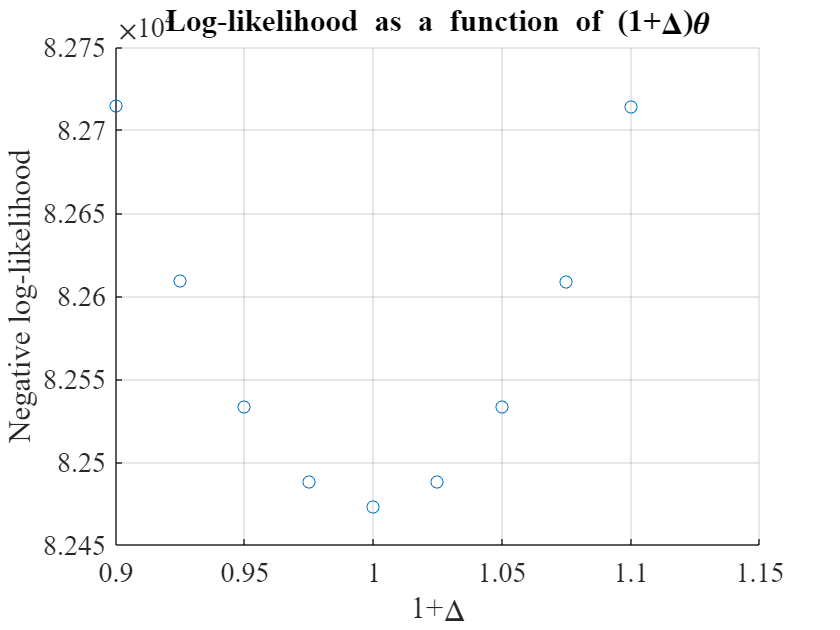


% Visualizing convergence
scatter((0.9:0.025:1.1),LikeFun((0.9:0.025:1.1).*ThetaHat))
xlabel('1+\Delta');
ylabel('Negative log-likelihood')
title('Log-likelihood as a function of (1+\Delta)\theta')

### Exercise: Pesendorfer and Schmidt-Dengler (2008) estimator

Another way to approach estimation is to consider the equilibrium condition on the conditional choice probabilities: in equilibrium, agents have common and correct beliefs about the strategies played by their opponents. Adopting the notation of Pesendorfer and Schmidt-Dengler (2008), we can represent the equilibrium condition as


$$\mathbf{p}  - \Psi(\mathbf{p}, \mathbf{f}, \theta) = 0$$


where $\Psi(\tilde{p}, \mathbf{f}, \theta)$ maps agents beliefs $\tilde{p}$, state transition probabilities $\mathbf{f}$, and utility parameters $\theta$ into a distribution over strategies. Because in equilibrium agents must have common and correct beliefs, we have a fixed point in $\mathbf{p}$ in the equation above. The key to using this formulation in estimation is that we already have a consistent estimator for the equilibrium conditional choice probabilities $\mathbf{p}$, as these are directly observed in the data. We also have a simple way to express the model-implied choice probabilities $\Psi(\mathbf{p},\mathbf{f},\theta)$, which is especially simple in our case due to the terminating action of exiting the market:


$$
\Psi(\mathbf{p},\mathbf{g},\theta)  =   \frac{\exp(v_2^{(i)}(x_t,s_t))}{1+\exp(v_2^{(i)}(x_t,s_t))} \\
 = \frac{\exp(u_2^{(i)}(x_t,s_t) - \beta \sum_{x_{t+1} \in X} \sum_{s_{t+1} \in S} [\log(p_1^{(i)}(x_{t+1},s_{t+1}) ] f_2^{(i)}(x_{t+1},s_{t+1} | x_t, s_t))}{1+\exp(u_2^{(i)}(x_t,s_t) - \beta \sum_{x_{t+1} \in X} \sum_{s_{t+1} \in S} [\log(p_1^{(i)}(x_{t+1},s_{t+1}) ] f_2^{(i)}(x_{t+1},s_{t+1} | x_t, s_t))} 
$$


The estimator minimizes the distance between the model-implied conditional choice probabilities and the CCPs estimated from the data:


$$\hat{\theta} = \arg\min_{\theta} \big(\hat{\mathbf{p}}  - \Psi(\hat{\mathbf{p}}, \mathbf{f}, \theta)\big)^TW\big(\hat{\mathbf{p}}  - \Psi(\hat{\mathbf{p}}, \mathbf{f}, \theta)\big)$$


Using the "fv", "Z", "ccp_hat", and "state_ind" variables, estimate the parameter vector $\theta$ using the minimum distance approach and $W=I$.

% Exercise code and output here


## Appendix: Data generation functions

function BigP=nfirms(pe1,pi1,bine,bini,ne,N)

Pe=zeros(ne+1,1);
for j=1:ne+1
    Pe(j)=bine(j)*(pe1^(j-1))*((1-pe1)^(ne-(j-1)));
end

Pi=zeros(N-ne+1,1);
for k=1:N-ne+1
    Pi(k)=bini(k)*(pi1^(k-1))*((1-pi1)^(N-ne-(k-1)));
end


BigP=zeros(1,N+1);
j=0;

while j<ne+1
    k=0;
    while k<N-ne+1
        BigP(j+k+1)=Pe(j+1)*Pi(k+1)+BigP(j+k+1);
        k=k+1;
    end
    j=j+1;
end
end




function [p,BigP,fv]=prob_entry(Util,trans,N,Xn,S,bine,Beta,A)
BigP=zeros(size(A,1),N+1);
fv=zeros(size(A,1),1);
eul=.5772;

p=exp(Util)./(1+exp(Util));

p0=zeros((N+1)*Xn*S*2,1);
p2=p;

while max(abs(p0-p2))>.0000000001
    p0=p2;

    for j=1:size(A,1)
        [~,ind1]=ismember([min(A(j,1)+A(j,4),N),A(j,2),A(j,3),0],A,'rows');
        [~,ind2]=ismember([max(A(j,1)+A(j,4)-1,0),A(j,2),A(j,3),1],A,'rows');
        BigP(j,:)=nfirms(p(ind1),p(ind2),bine(N-A(j,1)+1,:),bine(A(j,1)+1,:),N-A(j,1),N);

        v=0;
        for s2=1:S
            v=v+trans(A(j,3)+1,s2)*BigP(j,:)*log(1-p(ismember(A,[(0:5)',repmat([A(j,2),s2-1,1],[6,1])],'rows')));
        end
        fv(j)=-v;

        tu=BigP(j,:)*Util(ismember(A,[(0:5)',repmat([A(j,2),A(j,3),A(j,4)],[6,1])],'rows'))-Beta*v+Beta*eul;
        p(j)=exp(tu)./(1+exp(tu));

    end
    p2=p;
end
fv=Beta*(fv+eul);
end


function [Firm,X,State,Y,Lfirm]=EntryDataGen(p,ctrans,S,Xn,Nf,Nm,T,bp,Tl,A)
Firm=zeros(Nm,T+Tl,Nf);
Lfirm=zeros(Nm,T+Tl+1,Nf);
X=unidrnd(Xn,Nm,1)-1;
State=zeros(Nm,T+Tl+1);
Y=zeros(Nm,T+Tl);

State(:,1)=unidrnd(S,Nm,1);

Draw1=rand(Nm,T+Tl,Nf);
Draw2=rand(Nm,T+Tl);
Draw3=randn(Nm,T+Tl);


for nm=1:Nm
    Nfirm=0;
    for t=1:T+Tl

        for nf=1:Nf
            [~,ind]=ismember([Nfirm-Lfirm(nm,t,nf),X(nm),State(nm,t)-1,Lfirm(nm,t,nf)],A,'rows');
            Firm(nm,t,nf)=p(ind)>Draw1(nm,t,nf);
        end

        Nfirm=sum(Firm(nm,t,:));
        Lfirm(nm,t+1,:)=Firm(nm,t,:);

        Y(nm,t)=[1 Nfirm X(nm)-1 State(nm,t)-1]*bp+Draw3(nm,t);

        State(nm,t+1)=1;

        for s=1:S-1

            State(nm,t+1)=State(nm,t+1)+(Draw2(nm,t)>ctrans(State(nm,t),s));
        end

    end

end

Firm=Firm(:,Tl+1:T+Tl,:);
State=State(:,Tl+1:T+Tl)-1;
Lfirm=Lfirm(:,Tl+1:T+Tl,:);
Y=Y(:,Tl+1:T+Tl);

end



### References

Aguirregabiria, V., & Mira, P. (2007). [Sequential estimation of dynamic discrete games](http://www.its.caltech.edu/~mshum/gradio/papers/aguirregabiria-mira.pdf). *Econometrica*, *75*(1), 1-53.

Aguirregabiria, V., Collard-Wexler, A., & Ryan, S. P. (2021). [Dynamic games in empirical industrial organization.](https://arxiv.org/pdf/2109.01725.pdf) In *Handbook of Industrial Organization* (Vol. 4, No. 1, pp. 225-343). Elsevier.

Arcidiacono, P., & Miller, R. A. (2011). [Conditional choice probability estimation of dynamic discrete choice models with unobserved heterogeneity](http://public.econ.duke.edu/~psarcidi/ccp0810.pdf). *Econometrica*, *79*(6), 1823-1867.

Bajari, P., Benkard, C. L., & Levin, J. (2007). [Estimating dynamic models of imperfect competition](https://www.nber.org/system/files/working_papers/w10450/w10450.pdf). *Econometrica*, *75*(5), 1331-1370.

Caoui, E. H., Hollenbeck, B., & Osborne, M. (2022). [The Impact of Dollar Store Expansion on Local Market Structure and Food Access.](https://elhadicaoui.github.io/files/dollarstores.pdf) *Available at SSRN 4163102*.

Collard‐Wexler, A. (2013). [Demand fluctuations in the ready‐mix concrete industry](https://pages.stern.nyu.edu/~acollard/Demand%20Fluctuations%20in%20the%20Ready-Mix%20Concrete%20Industry.pdf). *Econometrica*, *81*(3), 1003-1037.

Miessi Sanches, F. A., Silva, D. J., & Srisuma, S. (2016). [Ordinary least squares estimation of a dynamic game model](https://openaccess.city.ac.uk/id/eprint/16624/1/). *International Economic Review*, *57*(2), 623-634.

Pesendorfer, M., & Schmidt-Dengler, P. (2008). [Asymptotic least squares estimators for dynamic games.](http://www.its.caltech.edu/~mshum/gradio/papers/pesendorferschmidt.pdf) *The Review of Economic Studies*, *75*(3), 901-928.

Ryan, S. P. (2012). [The costs of environmental regulation in a concentrated industry](https://dspace.mit.edu/bitstream/handle/1721.1/73601/Ryan_The%20Costs.pdf?sequence=1&isAllowed=y). *Econometrica*, *80*(3), 1019-1061.

Srisuma, S. (2013). [Minimum distance estimators for dynamic games](https://onlinelibrary.wiley.com/doi/pdf/10.3982/QE266). *Quantitative Economics*, *4*(3), 549-583.